clr;
obj = Gmodel('Bunny.stl');

* Loaded mesh = <a href="">Bunny.stl
</a>* Vertices  = 43.32k 
* Polycount = 86.63k 


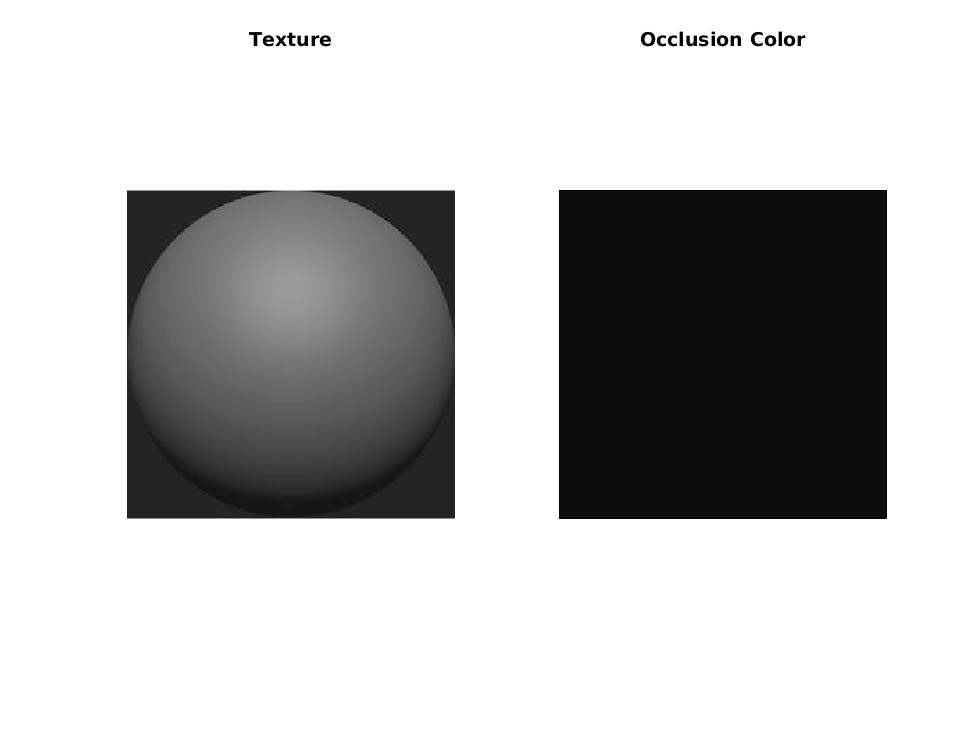

Texture  = grey; 
Occlusion = [0.05 0.05 0.05];

figure;
subplot(1,2,1); 
    image(Texture);
    axis equal;
    axis off;
    title('Texture');

subplot(1,2,2);
    showcolor(Occlusion);
    axis equal;
    axis off;
    title('Occlusion Color');

obj.set('Texture',Texture,...
        'Occlusion',Occlusion,...
        'AO',true,...
        'AOPower',5.0,...
        'AORadius',0.15);

obj.bake().render();

* Baking ambient ccclusion... (100 %) Done! 


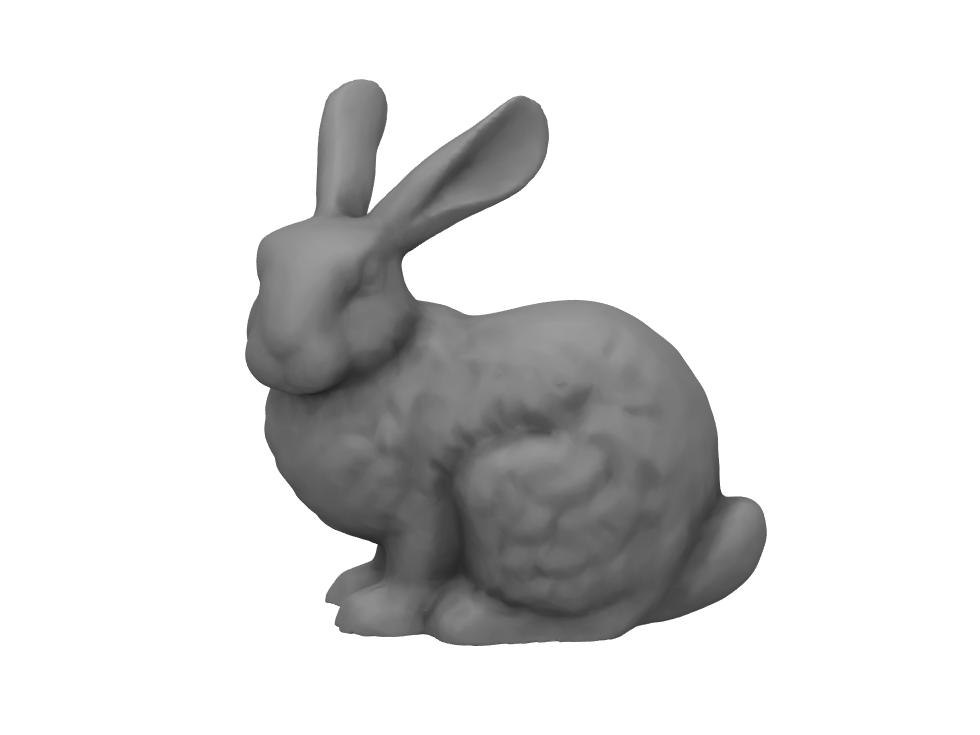


    view(0,15); 
    obj.update();

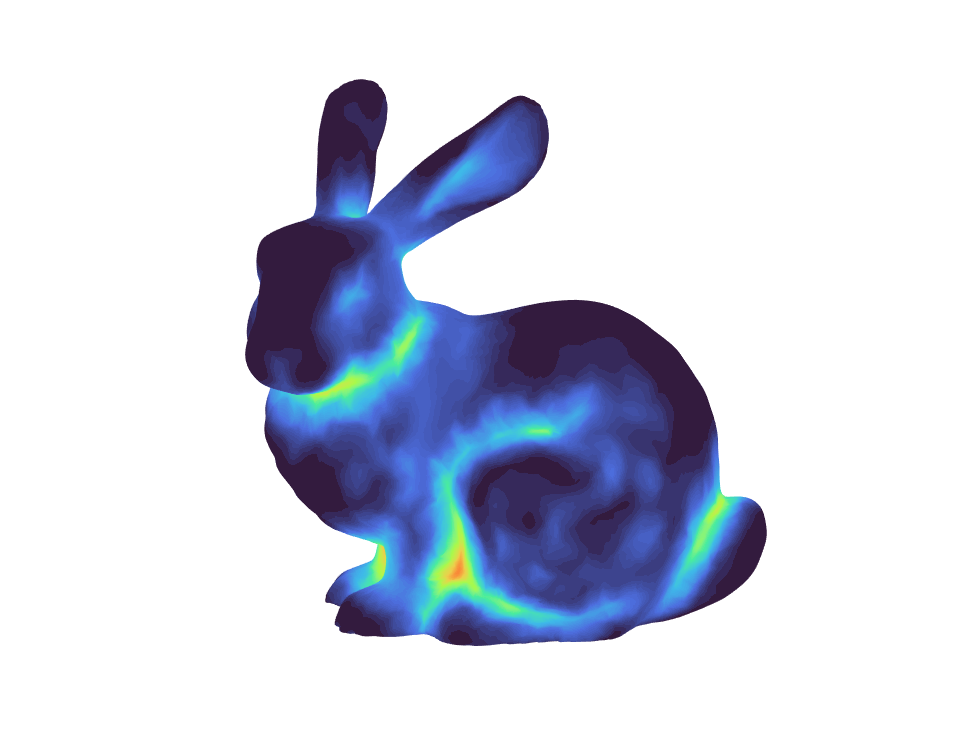

obj.showMap('AO');